## Import data

import data from ../data/SDSS_merge.dat and FIRST_merge.dat. Total rows are 17,189.


DataFileFolder = '../data/';
SelData = importdata([DataFileFolder,'sdss_merge.dat']);
SDSS = readtable([DataFileFolder,'SDSS_merge.csv']);
FIRST = readtable([DataFileFolder,'FIRST_merge.csv']);

Convert Position angle in range of [-90,90].

DeltaAlpha = deltaPAmodificaiton(SelData(:,6)-SelData(:,7));

% SelData(SelData(:,7)> 90,7) =  SelData(SelData(:,7)> 90,7) - 180;
% SelData(SelData(:,6)>90,6) = SelData(SelData(:,6)>90,6) -180;
SelData(:,7) = PAmodificaiton(SelData(:,7));
SelData(:,6) = PAmodificaiton(SelData(:,6));
SDSS.PA = PAmodificaiton(SDSS.PA);
SDSS.uPA = PAmodificaiton(SDSS.uPA);
SDSS.gPA = PAmodificaiton(SDSS.gPA);
SDSS.iPA = PAmodificaiton(SDSS.iPA);
FIRST.PA = PAmodificaiton(FIRST.PA);

BoverAsdss = SelData(:,9);
Con = SelData(:,8);
rMag = SelData(:,4);
uMag = SelData(:,5);
baxis = SelData(:,19);
aaxis = SelData(:,18);
paSDSS = SelData(:,7) ;
paFIRST = SelData(:,6);
PAdiff = deltaPAmodificaiton(SDSS.PA - FIRST.PA);

## Section 3.1

### Figure 1 Comparison of the PA measured in different bands. 

*The histograms are of the percentage of galaxies in each of the bins. The solid line represents the comparison between r and g, the dotted line that between g and i and the dashed line between i and r. *

bins = 18;
PAdiffrg = deltaPAmodificaiton(SDSS.PA - SDSS.gPA);
PAdiffgi = deltaPAmodificaiton(SDSS.iPA - SDSS.gPA);
PAdiffri = deltaPAmodificaiton(SDSS.PA - SDSS.iPA);

Plot

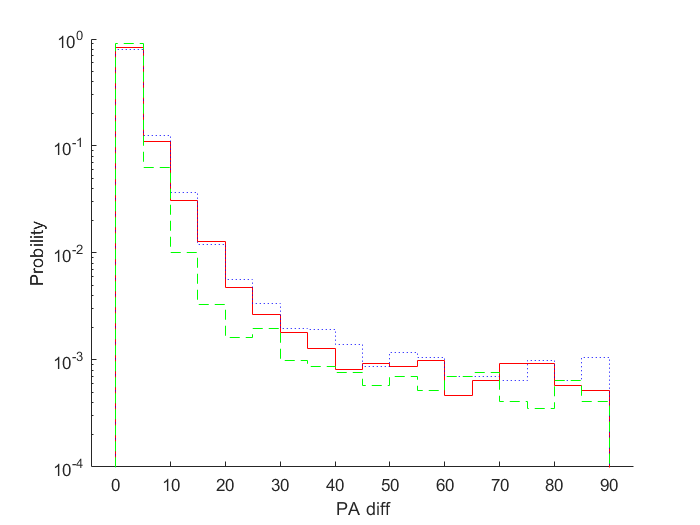

figure
hold on
histogram(PAdiffrg,bins,'LineStyle',"-","EdgeColor","r","DisplayStyle","stairs","Normalization",'probability')
histogram(PAdiffgi,bins,'LineStyle',":","EdgeColor","b","DisplayStyle","stairs","Normalization",'probability')
histogram(PAdiffri,bins,'LineStyle',"--","EdgeColor","g","DisplayStyle","stairs","Normalization",'probability')
set(gca,'Yscale','log')
xlabel('PA diff')
ylabel('Probility')

### Figure 2. The percentage of galaxies against the PA difference measured in the r and u bands.

*The solid line has 0.6 < b/a < 0.8, dotted line 0.4 < b/a < 0.6 and dashed line b/a < 0.4. The equivalent histogram for all values of the axial ratio is the dashed line in Fig. 1*

However, it is a problem that b/a value in SDSS catalog is different from FIRST catalog which lead to different figure 2. In my opinion, b/a value is more convincing in FIRST catalog because b/a in SDSS is fitted by exponential or de V .

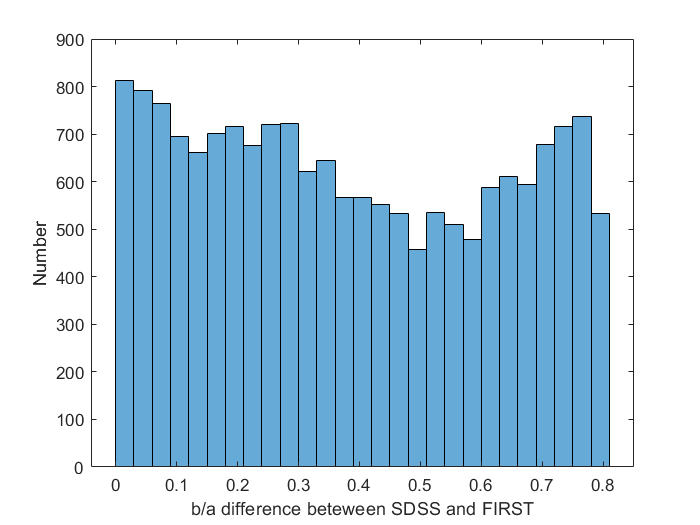

figure
BA = FIRST.Min./ FIRST.Maj ;
histogram(abs(SDSS.BA - BA))
xlabel('b/a difference beteween SDSS and FIRST')
ylabel('Number')

select catalog with SDSS b/a catalog. SDSS.BA means b/a.

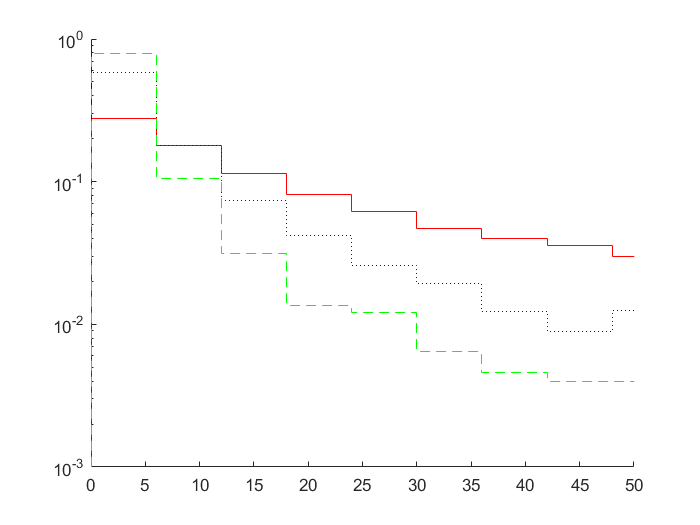

PAdiffru68 = deltaPAmodificaiton(SDSS.PA(SDSS.BA >0.6) - SDSS.uPA(SDSS.BA >0.6) );
PAdiffru46 = deltaPAmodificaiton( ...
    SDSS.PA(SDSS.BA >0.4 & SDSS.BA <= 0.6) - SDSS.uPA(SDSS.BA >0.4 & SDSS.BA <= 0.6) );
PAdiffru4 = deltaPAmodificaiton(SDSS.PA(SDSS.BA <= 0.4 & SDSS.BA > 0) - SDSS.uPA(SDSS.BA <= 0.4 & SDSS.BA > 0) );
PAdiffru0 = deltaPAmodificaiton(SDSS.PA(SDSS.BA == 0) - SDSS.uPA(SDSS.BA == 0) );
figure
hold on; bins = 15;
histogram(PAdiffru68,bins,'LineStyle',"-","EdgeColor","r","DisplayStyle","stairs","Normalization",'probability')
histogram(PAdiffru46,bins,'LineStyle',":","EdgeColor","b","DisplayStyle","stairs","Normalization",'probability')
histogram(PAdiffru4,bins,'LineStyle',"--","EdgeColor","g","DisplayStyle","stairs","Normalization",'probability')
histogram(PAdiffru0,bins,'LineStyle',"-","EdgeColor","k","DisplayStyle","stairs","Normalization",'probability')
set(gca,'Yscale','log')
ylim([1e-3 1])
xlim([0 50])

select catalog with FIRST b/a catalog

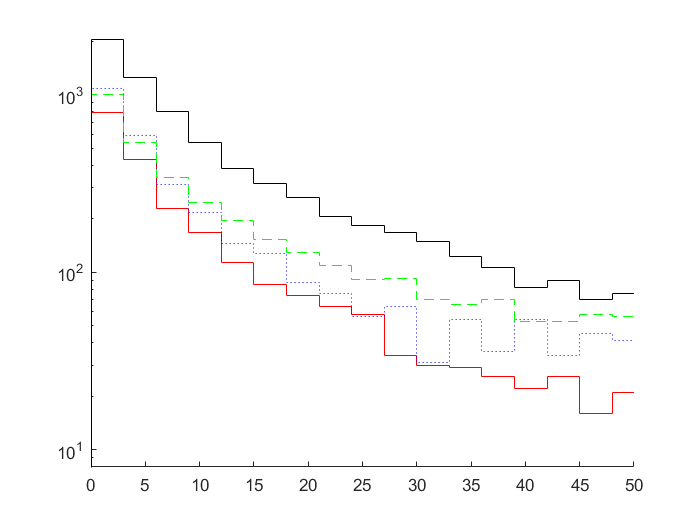


PAdiffru68 = deltaPAmodificaiton(SDSS.PA(BA >0.6) - SDSS.uPA(BA >0.6) );
PAdiffru46 = deltaPAmodificaiton( ...
    SDSS.PA(BA >0.4 & BA <= 0.6) - SDSS.uPA(BA >0.4 & BA <= 0.6) );
PAdiffru4 = deltaPAmodificaiton(SDSS.PA(BA <= 0.4 & BA > 0) - SDSS.uPA(BA <= 0.4 & BA > 0) );
PAdiffru0 = deltaPAmodificaiton(SDSS.PA(BA == 0) - SDSS.uPA(BA == 0) );
figure

hold on; bins = 30;
histogram(PAdiffru68,bins,'LineStyle',"-","EdgeColor","r","DisplayStyle","stairs")
histogram(PAdiffru46,bins,'LineStyle',":","EdgeColor","b","DisplayStyle","stairs")
histogram(PAdiffru4,bins,'LineStyle',"--","EdgeColor","g","DisplayStyle","stairs")
histogram(PAdiffru0,bins,'LineStyle',"-","EdgeColor","k","DisplayStyle","stairs")
set(gca,'Yscale','log')
% ylim([1e-3 1])
xlim([0 50])

### Figure 3. Histograms of $\Delta \alpha$, $\alpha_{\textrm{SDSS}}$ and $\alpha_{\textrm{FIRST}}$ using 18 bins for all 14,302 galaxies.

*Included also are the Poisson errors for each bin. *$\Delta \alpha$* is defined to be the acute angle between the two PA *$\alpha_{\textrm{SDSS}}$* and *$\alpha_{\textrm{FIRST}}$*.*

* Battye&Browne2009 *

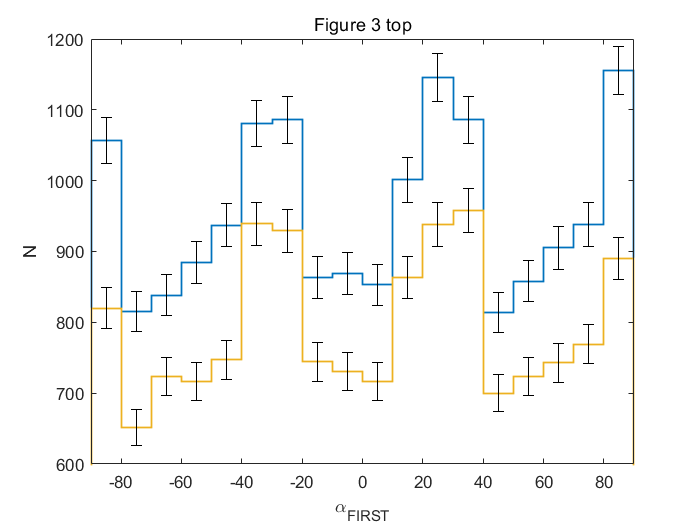

bins = 18;
Edge180 = linspace(-90,90,bins+1);
Edge90 = linspace(0,90,bins+1);

figure
[h1,e1] = histerror(FIRST.PA,0,Edge180);
[h2,e2] = histerror(paFIRST,0,Edge180);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([-90 90]); ylim([600 1200])
ylabel('N');xlabel('\alpha_{FIRST}')
title('Figure 3 top')

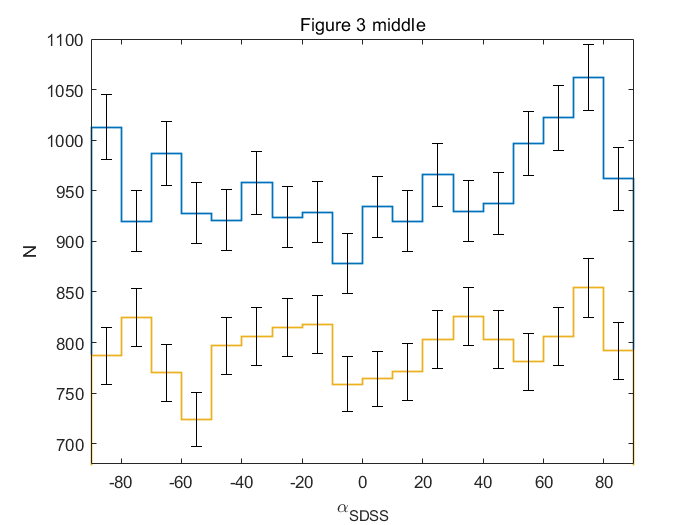


% h1.DisplayName='Battye&Browne2009';
% h2.DisplayName = 'Haotian';
% e1.DisplayName = '';
% e2.DisplayName = '';
% legend 


figure
[h1,e1] = histerror(SDSS.PA,0,Edge180);
hold on 
[h2,e2] = histerror(paSDSS,0,Edge180);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([-90 90]); ylim([680 1100])
ylabel('N');xlabel('\alpha_{SDSS}')
title('Figure 3 middle')
hold off

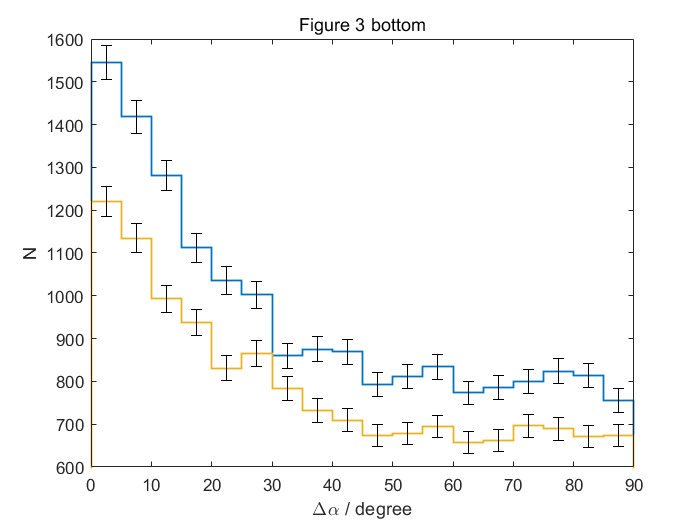


figure

[h2,e2] = histerror(deltaPAmodificaiton(SDSS.PA - FIRST.PA),0,Edge90);
hold on
[h1,e1] = histerror(DeltaAlpha,0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;

hold off

ylim([600 1600])
ylabel('N')
xlim([0 90])
xlabel('\Delta\alpha / degree')
title('Figure 3 bottom')

### Figure 4. Equivalent to Fig. 3 but for six bins.

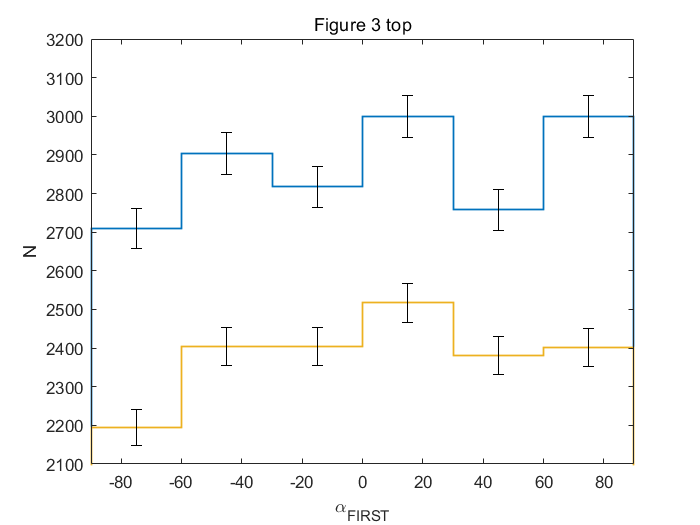

bins = 6;
Edge180 = linspace(-90,90,bins+1);
Edge90 = linspace(0,90,bins+1);

figure
[h1,e1] = histerror(FIRST.PA,0,Edge180);
[h2,e2] = histerror(paFIRST,0,Edge180);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([-90 90]); 
ylim([2100 3200])
ylabel('N');xlabel('\alpha_{FIRST}')
title('Figure 3 top')

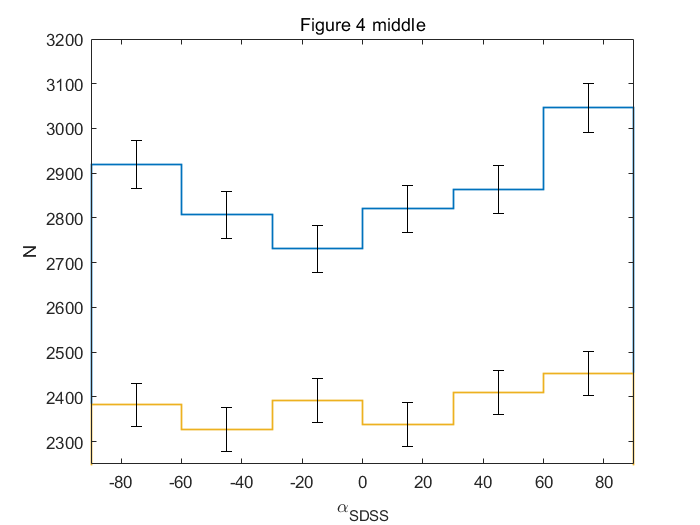


% h1.DisplayName='Battye&Browne2009';
% h2.DisplayName = 'Haotian';
% e1.DisplayName = '';
% e2.DisplayName = '';
% legend 


figure
[h1,e1] = histerror(SDSS.PA,0,Edge180);
hold on 
[h2,e2] = histerror(paSDSS,0,Edge180);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([-90 90]); ylim([2250 3200])
ylabel('N');xlabel('\alpha_{SDSS}')
title('Figure 4 middle')
hold off

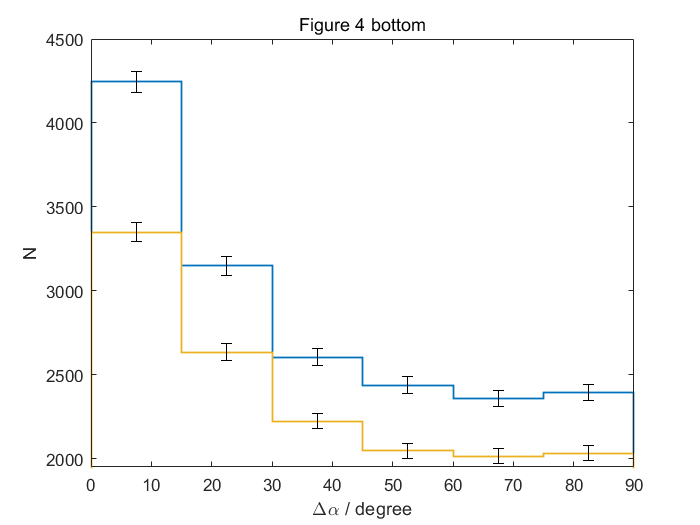


figure

[h2,e2] = histerror(PAdiff,0,Edge90);
hold on
[h1,e1] = histerror(DeltaAlpha,0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;

hold off

ylim([1950 4500])
ylabel('N')
xlim([0 90])
xlabel('\Delta\alpha / degree')
title('Figure 4 bottom')

Locations comparison

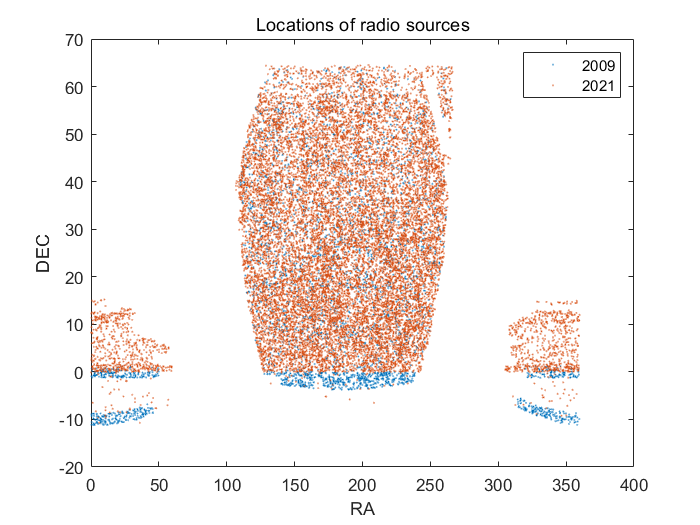

figure

plot(SelData(:,1),SelData(:,2),'.','MarkerSize',1);
hold on
plot(SDSS.raF,SDSS.decF,'.','MarkerSize',1);
% plot(FIRST.RA,FIRST.DEC,'.');
xlabel('RA');ylabel('DEC')
legend('2009','2021')
title('Locations of radio sources')

## Section 3.2

### Figure 5 split u-r <3, u-r >3, c<3, and c>3

c<3

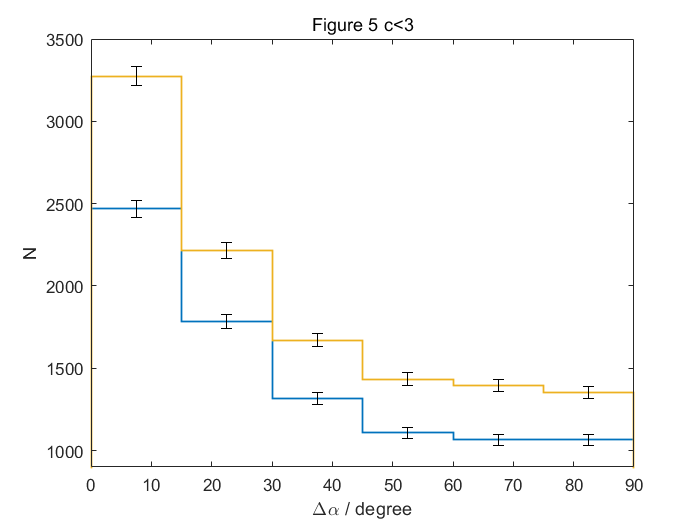

figure
% SelectedRow = ( SelData(:,5)-SelData(:,4));
SelectedRow = SelData(:,8)< 3;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
[h2,e2] = histerror(PAdiff(SDSS.concentration<3),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([900 3500])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 5 c<3')
hold off

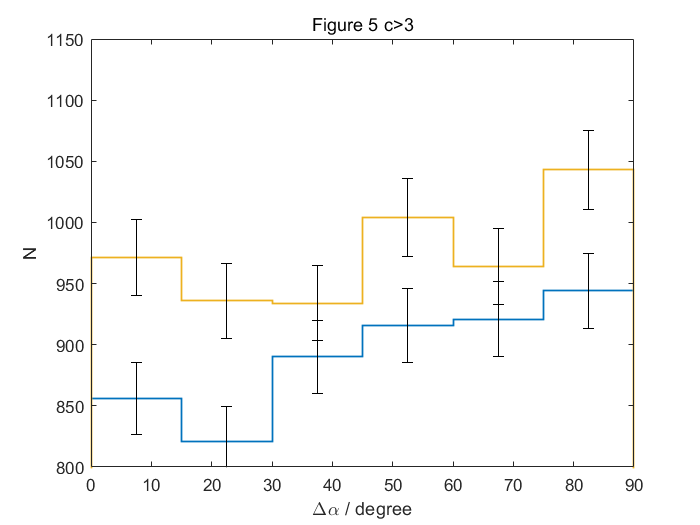

figure
% SelectedRow = ( SelData(:,5)-SelData(:,4));
SelectedRow = SelData(:,8) > 3;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
[h2,e2] = histerror(PAdiff(SDSS.concentration>3),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([800 1150])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 5 c>3')
hold off

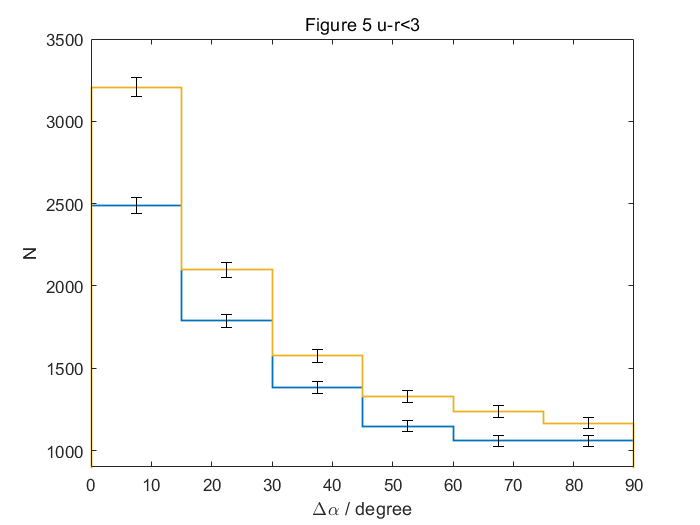

figure
SelectedRow = ( SelData(:,5)-SelData(:,4)) < 3;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
[h2,e2] = histerror(PAdiff((SDSS.u -SDSS.r)<3),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([900 3500])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 5 u-r<3')
hold off

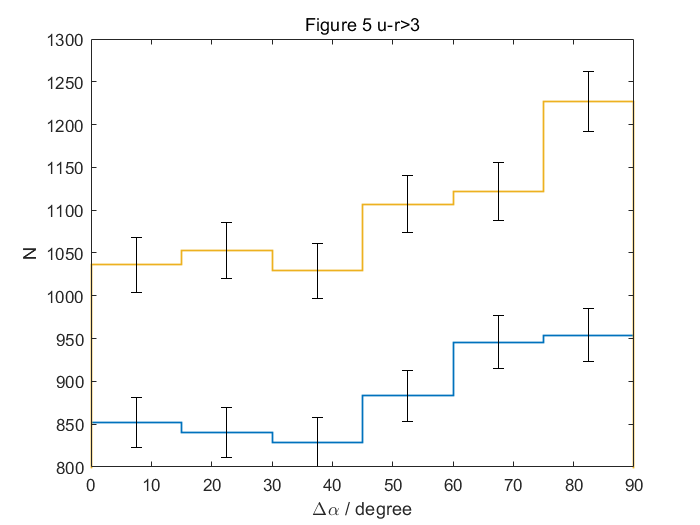

figure
SelectedRow = ( SelData(:,5)-SelData(:,4)) > 3;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
[h2,e2] = histerror(PAdiff((SDSS.u -SDSS.r)>3),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([800 1300])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 5 u-r>3')
hold off

## Section 3.3 Principal component analysis

### Figure 6. Scatter plot of the colour u − r versus c 

Principal component analysis

[Principal component analysis of raw data - MATLAB pca - MathWorks China](https://ww2.mathworks.cn/help/stats/pca.html?lang=en)

[coeff,~,latent]= pca([Con,uMag - rMag])

coeff =     0.2620    0.9651
    0.9651   -0.2620


latent =     0.6512
    0.1076


Standard deviation

sqrt(latent)

ans =     0.8070
    0.3281



$$$$
\begin{array}{l}
C_{1}=0.965 c-0.262(u-r) \\
C_{2}=0.262 c+0.965(u-r)
\end{array}
$$$$


*Scatter plot of the colour u − r versus c for the whole sample of 14 302 galaxies. Included also are the lines C1 = 2.0 (dashed line) and C2 = 3.5 (solid line).*

figure
plot(SelData(:,5)-SelData(:,4),SelData(:,8),'.r','MarkerSize',0.5);
hold on

Draw the line where C1 = 2.0 and C2 =3.5

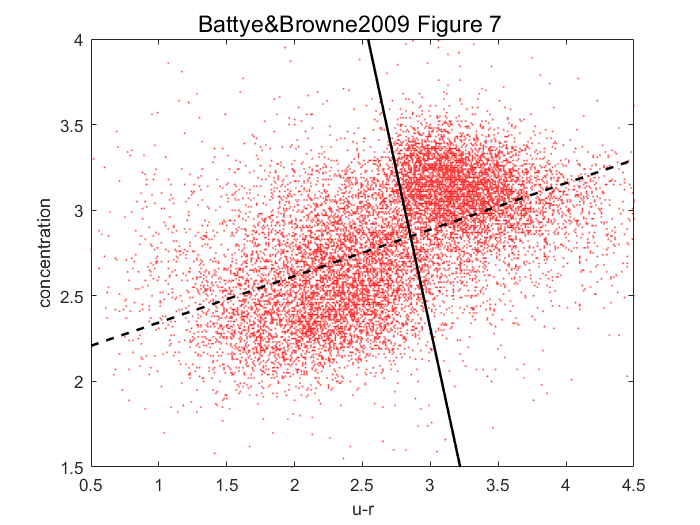

X = linspace(0.5,4.5,1000);
C1 = 2;C2 = 3.5;
Y = (C2 - 0.965.*X)./0.262;
plot(X,Y,'-k','LineWidth',1.5);

Y = (C1 + 0.262.*X)./0.965;
plot(X,Y,'--k','LineWidth',1.5)

ylim([1.5 4])
xlim([0.5 4.5])
xlabel('u-r')
ylabel('concentration')
sgtitle('Battye&Browne2009 Figure 7')

figure
plot(SelData(:,5)-SelData(:,4),SelData(:,8),'.r','MarkerSize',0.5);
hold on

Draw the line where C1 = 2.0 and C2 =3.5

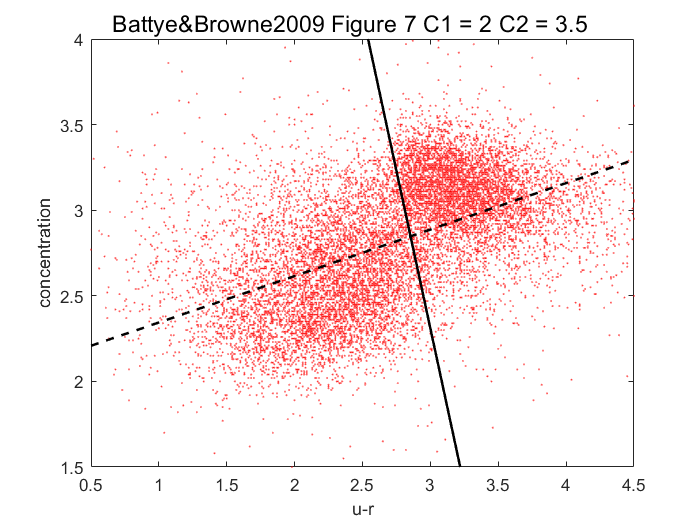

X = linspace(0.5,4.5,1000);
C1 = 2;C2 = 3.5;
Y = (C2 - 0.965.*X)./0.262;
plot(X,Y,'-k','LineWidth',1.5);

Y = (C1 + 0.262.*X)./0.965;
plot(X,Y,'--k','LineWidth',1.5)

ylim([1.5 4])
xlim([0.5 4.5])
xlabel('u-r')
ylabel('concentration')
sgtitle('Battye&Browne2009 Figure 7 C1 = 2 C2 = 3.5')

[coeff,~,latent] = pca([SDSS.concentration,SDSS.u - SDSS.r])

coeff =     0.0492    0.9988
    0.9988   -0.0492


latent =     1.4337
    0.1643


Standard deviation

sqrt(latent)

ans =     1.1974
    0.4053



$$$$
\begin{array}{l}
C_{1}=0.9988 c-0.0492(u-r) \\
C_{2}=0.0492 c+0.9988(u-r)
\end{array}
$$$$


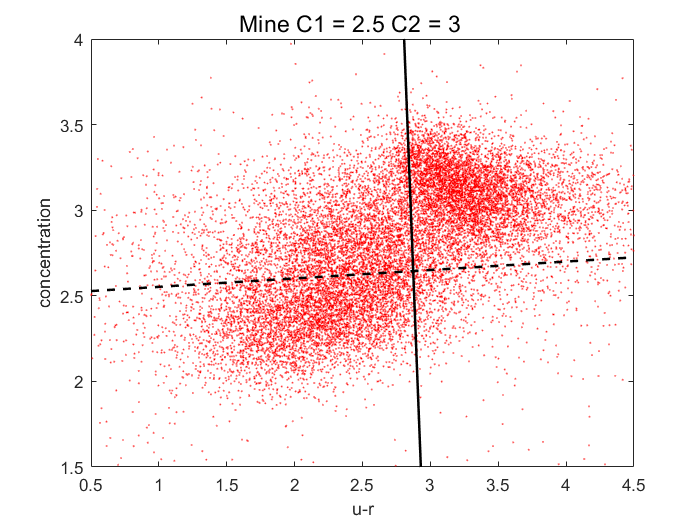

figure
plot(SDSS.u- SDSS.r,SDSS.concentration,'.r','MarkerSize',0.5);
hold on
X = linspace(0.5,4.5,1000);
C1 = 2.5;C2 = 3;
Y = (C2 - coeff(2,1).*X)./coeff(1,1);
plot(X,Y,'-k','LineWidth',1.5);

Y = (C1 + coeff(1,1).*X)./coeff(2,1);
plot(X,Y,'--k','LineWidth',1.5)

ylim([1.5 4])
xlim([0.5 4.5])
xlabel('u-r')
ylabel('concentration')
sgtitle('Mine C1 = 2.5 C2 = 3')

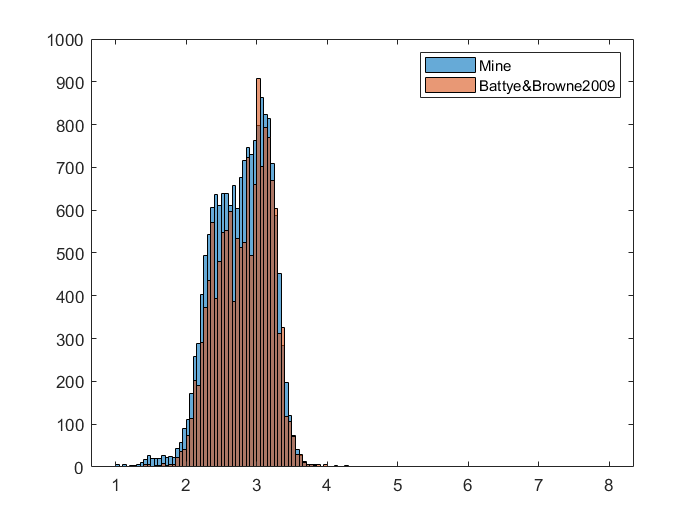

figure 
edge = 1:0.05:8;
histogram(SDSS.concentration,edge)
hold on; 
 histogram(Con,edge)
 legend('Mine','Battye&Browne2009')

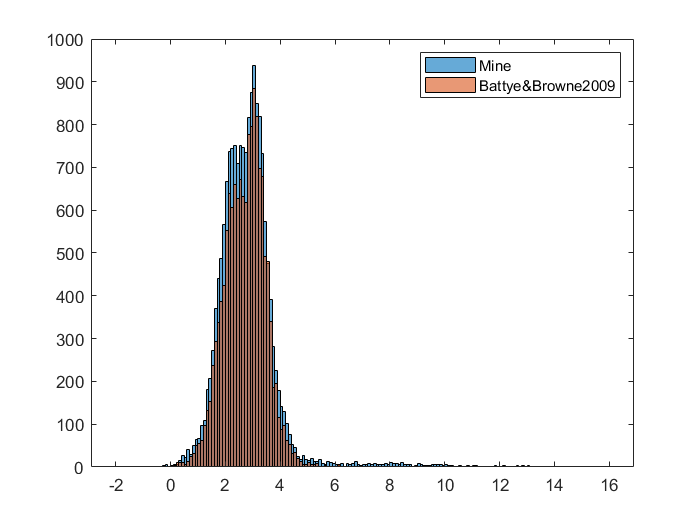

figure 
edge = -2:0.1:16;
histogram(SDSS.u - SDSS.r,edge)
hold on; 
 histogram(uMag- rMag,edge)
 legend('Mine','Battye&Browne2009')

x =SDSS.u - SDSS.r;
y = SDSS.concentration;
SelectedRow = x>=0.5 &x <=4.5 & y>=1.5 & y<=4;
sum(SelectedRow)/length(SelectedRow)

ans = 0.9574

[coeff,~,latent] = pca([x(SelectedRow),y(SelectedRow)])

coeff =     0.9498   -0.3130
    0.3130    0.9498


latent =     0.5689
    0.0957


sqrt(latent)

ans =     0.7543
    0.3093


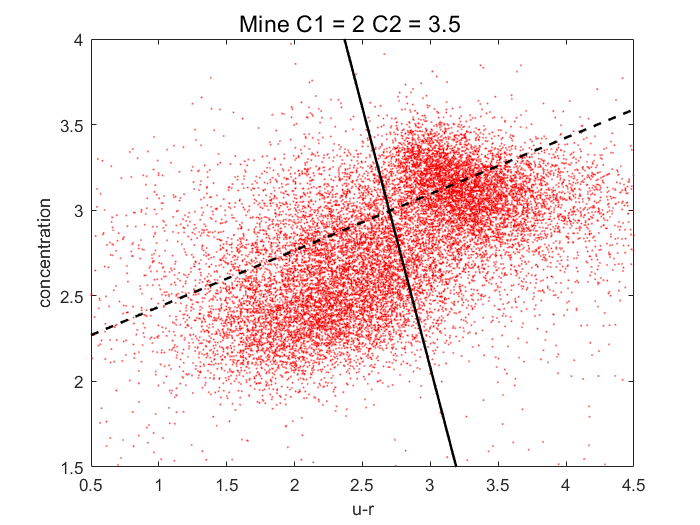

figure
plot(SDSS.u- SDSS.r,SDSS.concentration,'.r','MarkerSize',0.5);
hold on
X = linspace(0.5,4.5,1000);
C1 = 2;C2 = 3.5;
Y = (C2 - coeff(1,1).*X)./coeff(2,1);
plot(X,Y,'-k','LineWidth',1.5);

Y = (C1 + coeff(2,1).*X)./coeff(1,1);
plot(X,Y,'--k','LineWidth',1.5)

ylim([1.5 4])
xlim([0.5 4.5])
xlabel('u-r')
ylabel('concentration')
sgtitle('Mine C1 = 2 C2 = 3.5')

x =uMag - rMag;
y = Con;
SelectedRow = x>=0.5 &x <=4.5 & y>=1.5 & y<=4;
sum(SelectedRow)/length(SelectedRow)

ans = 0.9842

[coeff,~,latent] = pca([x(SelectedRow),y(SelectedRow)])

coeff =     0.9431   -0.3326
    0.3326    0.9431


latent =     0.5245
    0.0898


sqrt(latent)

ans =     0.7243
    0.2997


### Figure 7 splits of the data on basis of PCA analysis

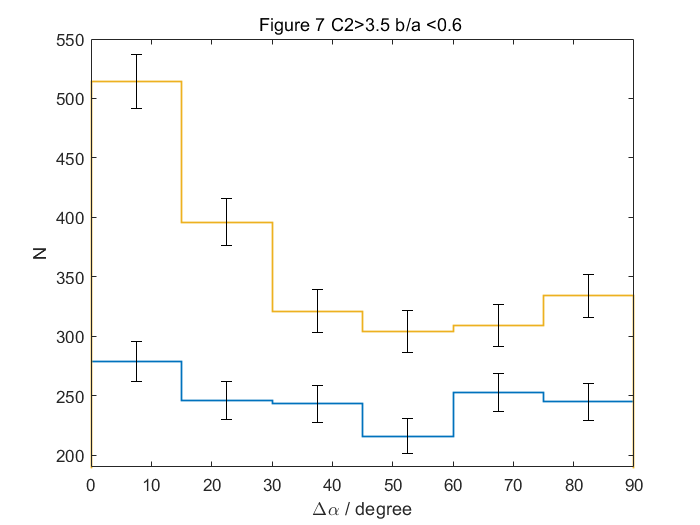

C2 = C2function(Con,uMag,rMag);

figure
SelectedRow = C2 > 3.5 & BoverAsdss  <=0.6;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
SelectedRow = ((0.3130*SDSS.concentration +  ...
    0.9498*(SDSS.u - SDSS.r)) > 3.5 ) & (SDSS.BA <= 0.6) ;
[h2,e2] = histerror(PAdiff(SelectedRow),0,Edge90);
e1.Color = 'k'; 
e2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlim([0 90]); ylim([190 550])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 7 C2>3.5 b/a <0.6 ')
hold off

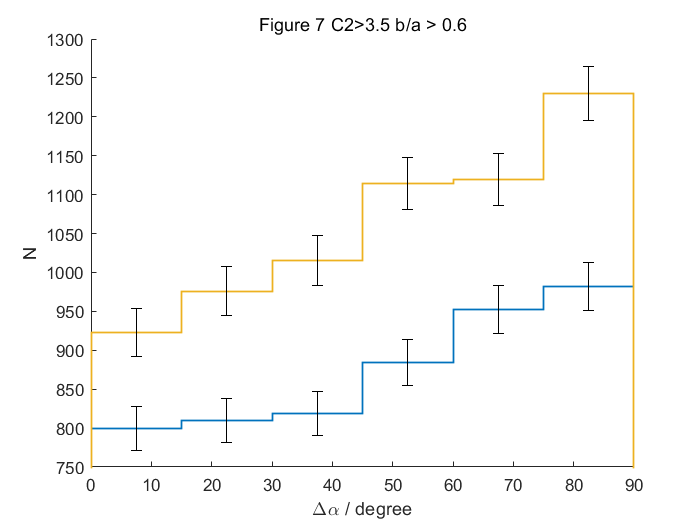



figure
hold on
SelectedRow = C2 > 3.5 & BoverAsdss >0.6;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
SelectedRow = ((0.3130*SDSS.concentration +  ...
    0.9498*(SDSS.u - SDSS.r)) > 3.5 ) & (SDSS.BA> 0.6) ;
[h2,e2] = histerror(PAdiff(SelectedRow),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([750 1300])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 7 C2>3.5 b/a > 0.6')
hold off

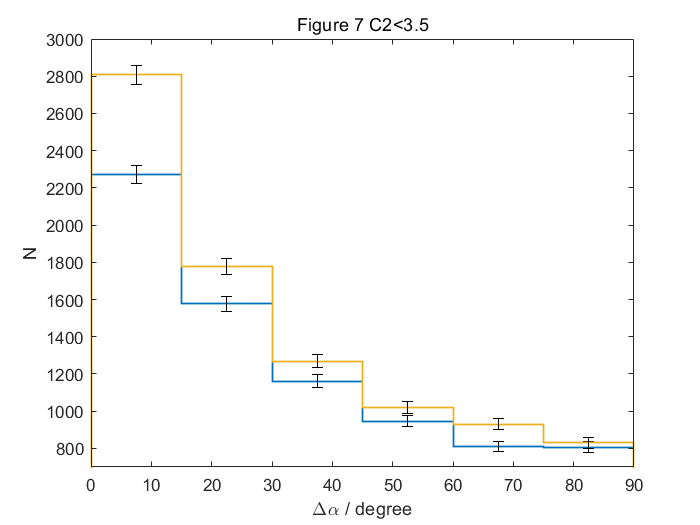


figure
SelectedRow = C2 < 3.5;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
SelectedRow = (0.3130*SDSS.concentration +  ...
    0.9498*(SDSS.u - SDSS.r)) < 3.5;
[h2,e2] = histerror(PAdiff(SelectedRow),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([700 3000])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 7 C2<3.5')
hold off

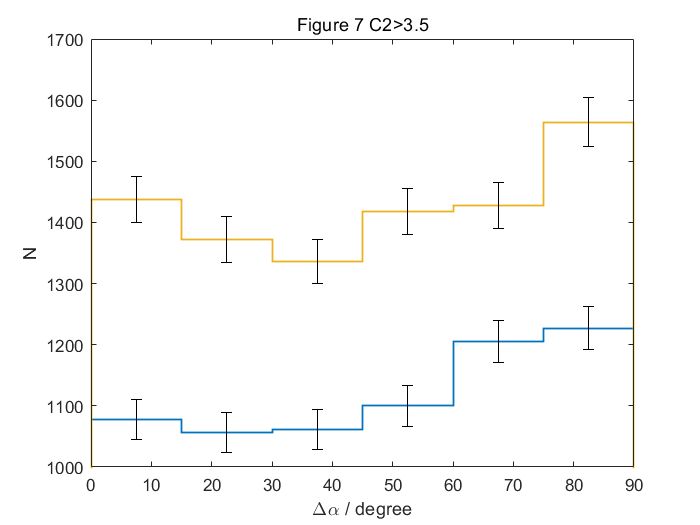

figure
SelectedRow = C2 > 3.5 ;
[h1,e1] = histerror(DeltaAlpha(SelectedRow),0,Edge90);
SelectedRow = (0.3130*SDSS.concentration +  ...
    0.9498*(SDSS.u - SDSS.r)) > 3.5;
[h2,e2] = histerror(PAdiff(SelectedRow),0,Edge90);
e1.Color = 'k'; e2.Color = 'k';
h1.LineWidth = 1;h2.LineWidth = 1;
xlim([0 90]); ylim([1000 1700])
ylabel('N');xlabel('\Delta\alpha / degree')
title('Figure 7 C2>3.5')
hold off

### Functions 

function c1 = C1function(c,u,r)
c1 = 0.965.*c - 0.262.*(u-r);
end
function c2 = C2function(c,u,r)
% C2function(c,u,r)
c2 = 0.262.*c + 0.965.*(u-r);
end
function Figure34withoutError(bins,title,paFIRST,paSDSS ...
    ,DeltaAlpha)

Edge180 = linspace(-90,90,bins+1);
Edge90 = linspace(0,90,bins+1);

subplot 311
% FIRST PA
histogram(paFIRST,Edge180,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5)
% ylim(ylimRange(1,:))
xlim([-90 90])
ylabel('N')
xlabel('\alpha_{FIRST}')
subplot 312
histogram(paSDSS,Edge180,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5)
% ylim(ylimRange(2,:))
xlim([-90 90])
ylabel('N')
xlabel('\alpha_{SDSS}')
subplot 313
h= histogram(DeltaAlpha,Edge90,'DisplayStyle',"stairs",'EdgeColor','r','LineWidth', 1.5);
% ylim(ylimRange(3,:))
ylabel('N')
xlim([0 90])
xlabel('\Delta\alpha')
sgtitle(title)
end
function PAmod = PAmodificaiton(PA)
check =sum(PA < -270 )+sum(PA > 270 );
if( check>0)
fprintf('warning %i Position angle are out of range. max: %f ; min: %f' ...
    ,check,max(PA),min(PA))

end
PA(PA>90) = PA(PA>90)  - 180;
PA(PA<-90) = PA(PA<-90)  + 180;
PAmod = PA;
end
function deltaPAmod = deltaPAmodificaiton(deltaPA)
deltaPA(deltaPA<0) = -deltaPA(deltaPA<0);
deltaPA(deltaPA>90) = 180- deltaPA(deltaPA>90);

deltaPAmod = deltaPA;
end